# 读取图片

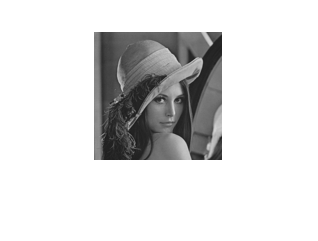

img=imread("input.bmp");
img_g=rgb2gray(img);
img2=im2double(img_g);
[srcW,srcH]=size(img2);
[dstW,dstH]=deal(1024,1024);
imshow(img2)

R=zeros(dstW,dstH);

## nearest

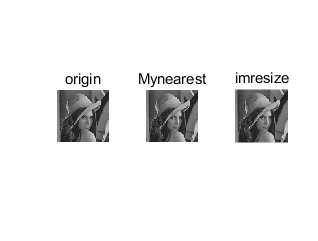

for x =1:dstW
    for y=1:dstH
        srcX=x*(srcW/dstW);
        dstX_p=round(srcX);
        srcY=y*(srcH/dstH);
        dstY_p=round(srcY);
        if dstY_p==0
            dstY_p=dstY_p+1;
        end
        if dstX_p==0
            dstX_p=dstX_p+1;
        end
        R(x,y)=img2(dstX_p,dstY_p);
    end
end
subplot(1,3,1)
imshow(img2)
title("origin")
subplot(1,3,2)
imshow(R)
title("Mynearest")
subplot(1,3,3)
imr=imresize(img2,[dstW,dstH],'Method','nearest');
imshow(imr)
title("imresize")

## bilinear

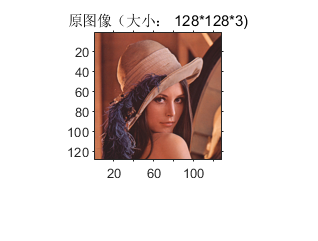

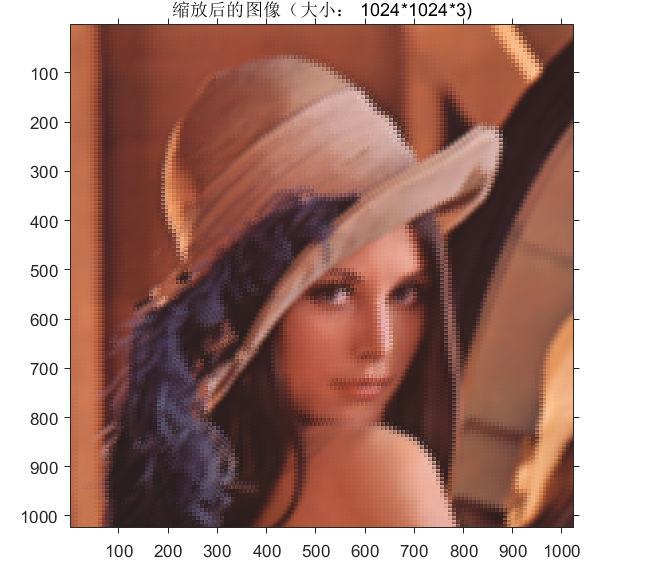

clear;
close all;
clc;
img = imread('input.bmp');
[ori,img_new] = imblizoom(img,8);
% [ori,img_new] = imblizoom('image/my_gray_512.jpg',0.5);
img_show(ori,img_new);

R=bicubic(img,8)

R = R(:,:,1) =

  列 1 至 999

    0.7725    0.7723    0.7721    0.7720    0.7719    0.7719    0.7719    0.7719    0.7719    0.7719    0.7720    0.7721    0.7723    0.7725    0.7728    0.7731    0.7733    0.7733    0.7731    0.7726    0.7719    0.7711    0.7701    0.7690    0.7678    0.7663    0.7648    0.7631    0.7613    0.7593    0.7572    0.7549    0.7525    0.7498    0.7470    0.7440    0.7409    0.7377    0.7344    0.7308    0.7269    0.7225    0.7176    0.7122    0.7067    0.7012    0.6952    0.6886    0.6811    0.6726    0.6627    0.6512    0.6379    0.6232    0.6073    0.5907    0.5737    0.5567    0.5399    0.5236    0.5061    0.4879    0.4694    0.4513    0.4343    0.4189    0.4057    0.3952    0.3867    0.3800    0.3748    0.3710    0.3684    0.3668    0.3661    0.3662    0.3680    0.3713    0.3757    0.3808    0.3863    0.3919    0.3970    0.4016    0.4064    0.4115    0.4166    0.4217    0.4266    0.4312    0.4352    0.4387    0.4416    0.4441    0.4463    0.4482    0.4500 

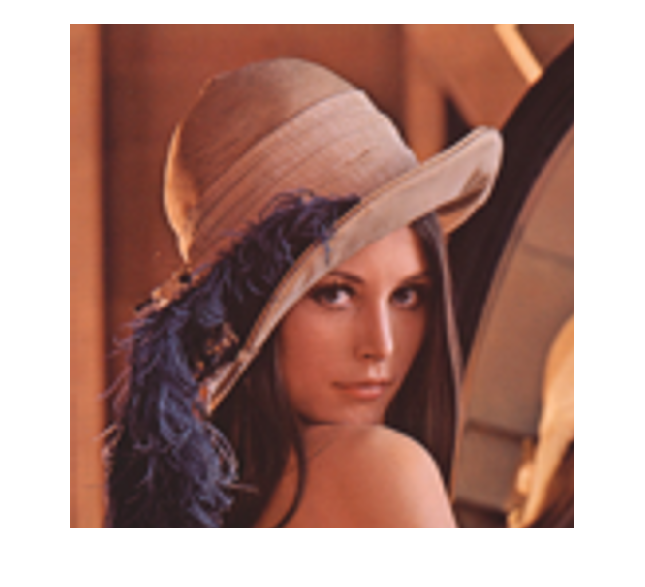

imshow(R)

function [ original,new_img ] = imblizoom( original,zmf )
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % %
%-----------------双线性插值法缩放矩阵或图像---------------------
% Input：
% original：原始图像图像文件名或矩阵（整数值（0~255））
% zmf：缩放因子，即缩放的倍数
% Output：
% original: 原始图像矩阵
% new_img: 缩放后的图像矩阵 
% Usage:
% [original,new_img] = imblizoom('ImageFileName',zmf)
% 对图像I进行zmf倍的缩放
% Or:
% [original,new_img] = imblizoom(I,zmf)
% 对矩阵I进行zmf倍的缩放
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
%% Step1 对数据进行预处理
if ~exist('original','var') || isempty(original)
    error('输入图像 I未定义或为空！');
end
if ~exist('zmf','var') || isempty(zmf) || numel(zmf) ~= 1
     error('位移矢量 zmf未定义或为空或 zmf中的元素超过2！');
end
if isstr(original)
    [original,M] = imread(original);
end
if zmf <= 0
     error('缩放倍数 zmf的值应该大于0！');
end
%% Step2 通过原始图像和缩放因子得到新图像的大小，并创建新图像
[height,width,channel] = size(original);
new_height = round(height*zmf); % 计算缩放后的图像高度，最近取整
new_width = round(width*zmf); % 计算缩放后的图像宽度，最近取整
new_img = zeros(new_height,new_width,channel); % 创建新图像

%% Step3 扩展原始矩阵I边缘
img_scale = zeros(height+2,width+2,channel); % 为了边界点考虑的
img_scale(2:height+1,2:width+1,:) = original;
% % ========================================================
% 为4周各添加的一行或列做值的初始化
% % ========================================================= 
% 为扩展而来的各边赋值
img_scale(1,2:width+1,:) = original(1,:,:);
img_scale(height+2,2:width+1,:) = original(height,:,:);
img_scale(2:height+1,1,:) = original(:,1,:);
img_scale(2:height+1,width+2,:) = original(:,width,:);
% 用原图的4个顶点为扩展而来的4个顶点赋值
img_scale(1,1,:) = original(1,1,:);
img_scale(1,width+2,:) = original(1,width,:);
img_scale(height+2,1,:) = original(height,1,:);
img_scale(height+2,width+2,:) = original(height,width,:);
%% ============================================================
% Step4 由新图像的某个像素（zi，zj）映射到原始图像(ii，jj)处， 并在原始
% 图像的(ii,jj)位置利用其周围4个像素点进行插值得到(ii,jj)处的像素值
% % ====================================================================
for zj = 1:new_width         % 对图像进行按列逐元素扫描
    for zi = 1:new_height
        % (zi,zj)表示在新图中的坐标，(ii,jj)表示在原图中的坐标
        % 注意：(ii,jj)不一定是整数
        ii = (zi-1)/zmf; jj = (zj-1)/zmf;
        i = floor(ii); j = floor(jj); % 向下取整得到在原图中坐标的整数部分
        u = ii - i; v = jj - j;       % 得到在原图中坐标的小数部分
        i = i + 1; j = j + 1;
        new_img(zi,zj,:) = (1-u)*(1-v)*img_scale(i,j,:) + u*(1-v)*img_scale(i,j+1,:)...
                    + (1-u)*v*img_scale(i+1,j,:) + u*v*img_scale(i+1,j+1,:);
    end
end
new_img = uint8(new_img);

end  
function img_show(original,new_img)
[height,width,channel] = size(original);
figure;imshow(original);
axis on
title(['原图像（大小： ',num2str(height),'*',num2str(width),'*',num2str(channel),')']);
[new_height,new_width,~] =size(new_img); 
figure;imshow(new_img);
axis on
title(['缩放后的图像（大小： ',num2str(new_height),'*',num2str(new_width),'*',num2str(channel)',')']); 
end

## Bicublc

function R = bicubic(src, scale)
%% 双三次插值
src = im2double(src);
% 判断是灰度图还是RGB图像
if ismatrix(src)
    R = zeros(floor(size(src) * scale));
else
    [height,width,channel] = size(src);
    new_height = round(height*scale); % 计算缩放后的图像高度，最近取整
    new_width = round(width*scale); % 计算缩放后的图像宽度，最近取整
    R = zeros(new_height,new_width,channel); % 创建新图像
end
[dstM, dstN, ~] = size(R);
% 扩展原图像
misrc = zeros([size(src, 1, 2) + 2 * floor(scale), size(R, 3)]);
for i = 1 : size(R, 3)
    tmp = padarray(src(:, :, i), [floor(scale), floor(scale)], 'symmetric');
    misrc(:, :, i) = tmp;
end
 
%逐像素点赋值
for dstX = 1 : dstM
    for dstY = 1 : dstN
        srcX = floor((dstX + 0.5) / scale - 0.5);
        srcY = floor((dstY + 0.5) / scale - 0.5);
        u = ((dstX + 0.5) / scale - 0.5) - srcX;
        v = ((dstY + 0.5) / scale - 0.5) - srcY;
        X1 = zeros(4, 4);  
        X2 = zeros(4, 4);  
        W1 = ones(4, 4); 
        W2 = ones(4, 4);   
        % Bicubic基函数
        for i = 1 : 4
            for j = 1 : 4
                X1(i, j) = abs(u - i + 2);
                X2(i, j) = abs(v - j + 2);
                if X1(i, j) <= 1
                    W1(i, j) = 1.5 * (X1(i, j)) ^ 3 - 2.5 * (X1(i, j)) ^ 2 + 1;
                else
                    if X1(i, j) < 2
                        W1(i, j) = (-0.5) * (X1(i, j)) ^ 3 + 2.5 * (X1(i, j)) ^ 2 - 4 * X1(i, j) + 2;
                    else
                        W1(i, j) = 0;
                    end
                end
                if X2(i, j) <= 1
                    W2(i, j) = 1.5 * (X2(i, j)) ^ 3 - 2.5 * (X2(i, j)) ^ 2 + 1;
                else
                    if  X2(i, j) < 2
                        W2(i, j) = (-0.5) * (X2(i, j)) ^ 3 + 2.5 * (X2(i, j)) ^ 2 - 4 * X2(i, j) + 2;
                    else
                        W2(i, j) = 0;
                    end
                end
            end
        end
        W = W1 .* W2;
        Z = ones(4, 4);  %16个源像素点矩阵
        O = ones(4, 4);  %16个加权后的源像素点矩阵
        for dstC = 1 : size(R, 3)
            for i = 1 : 4
                for j = 1 : 4
                    Z(i, j) = misrc(srcX - 2 + i + round(scale), srcY - 2 + j + round(scale), dstC);
                    O(i, j) = W(i, j) .* Z(i,j);
                end
            end
            O1 = sum(sum(O));
            R(dstX, dstY, dstC) = O1;
        end
    end
end
end
